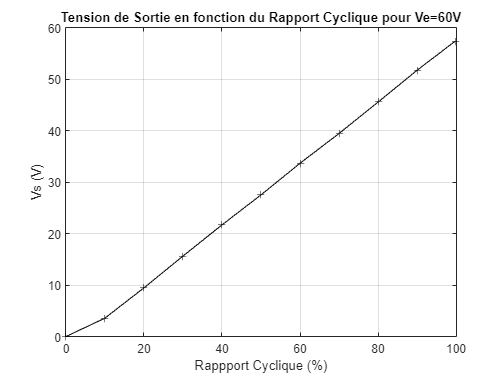

clc

% CONVERSION Partie 1
% Ve = 60V
rapport_cycle=[99.68 90 80 70 60 50 40 30 20 10 0];
Vs=[57.4 51.8 45.60 39.50 33.70 27.55 21.71 15.64 9.46 3.57 0];

plot(rapport_cycle,Vs,'k+-'); % Vs=f(alpha)
title('Tension de Sortie en fonction du Rapport Cyclique pour Ve=60V')
xlabel('Rappport Cyclique (%)'); ylabel('Vs (V)')
grid on

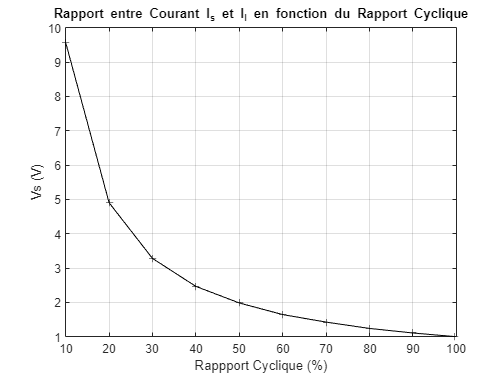



Ie=[2 1.80 1.64 1.42 1.23 1.02 0.82 0.61 0.41 0.21 0];
Is=[2.00 1.99 2.03 2.02 2.02 2.02 2.02 2 2.01 2.01 0];

plot(rapport_cycle,Is./Ie,'k+-'); %%Ie/Is=f(alpha)
title('Rapport entre Courant I_s et I_l en fonction du Rapport Cyclique')
xlabel('Rappport Cyclique (%)'); ylabel('Vs (V)')
grid on


% Image d'ALI.

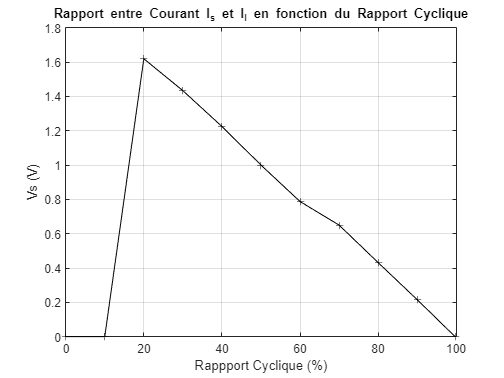

% Ondulation de courant Il

delta_Il=[0 215 431.25 650 787.5 1000 1225 1434 1620 0 0]*1e-3;

plot(rapport_cycle,delta_Il,'k+-');
title('Rapport entre Courant I_s et I_l en fonction du Rapport Cyclique')
xlabel('Rappport Cyclique (%)'); ylabel('Vs (V)')
grid on

On modifie uniquement un seul des paramètres à la fois :

- Rapport cyclique : faire varier le rapport cyclique fait varier également la tension de sortie, entre 0 et Ve.

- Ve : faire varier la tension d'entrée fera également et uniquement varier la tension de sortie. Si la tension d'entrée est cependant inférieure à la tension de sortie du hacheur, alors ce dernier se mettra en sécurité.

- R : faire varier la charge changera la valeur du courant Is, ce qui entrainera également un variation de Ie.

- Fe : modifier la fréquence de découpage aura un impact sur la qualité du signal en sortie du hacheur.Plus la fréquence sera faible, plus le régime transitoire sera apparent sur le signal (signal en dent de scie).

- L : enfin, modifier L aura le même effet que de faire varier Fe. La diminuer fera qu'elle ne pourra lisser correctement, et donc rendra les créneaux visibles (signal en dent de scie).

[http://tsi.ljf.free.fr/ATS/docs/S2I/CI3A/Hacheur.pdf](http://tsi.ljf.free.fr/ATS/docs/S2I/CI3A/Hacheur.pdf) (page 10)

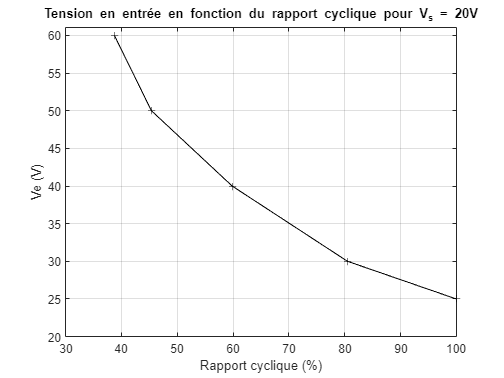

% CONVERSION Partie 2
Ps=60;
alpha3=[100 80.5 59.83 45.36 38.73];
Ve2=[25 30 40 50 60];
Ie2=[3.09 2.46 1.82 1.45 1.28];

plot(alpha3,Ve2,'k+-');
title('Tension en entrée en fonction du rapport cyclique pour V_s = 20V')
xlabel('Rapport cyclique (%)'); ylabel('Ve (V)')
ylim([20 61])
grid on

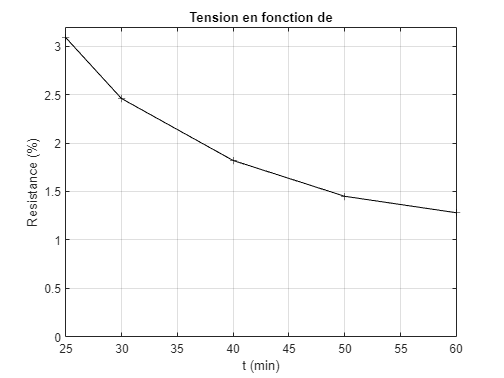


plot(Ve2,Ie2,'k+-');
title('Tension en fonction de')
xlabel('t (min)'); ylabel('Resistance (%)')
ylim([0 max(Ie2)+0.1])
grid on

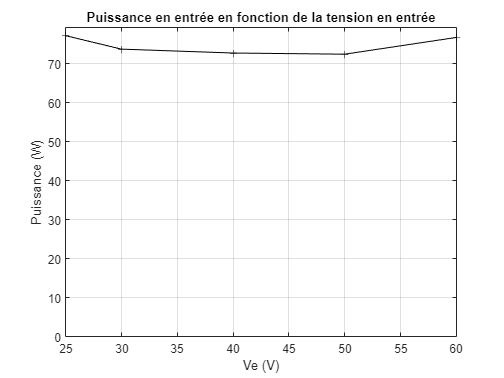



Pe=Ve2.*Ie2;

plot(Ve2,Pe,'k+-');
title('Puissance en entrée en fonction de la tension en entrée')
xlabel('Ve (V)'); ylabel('Puissance (W)')
ylim([0 max(Pe)+2])
grid on

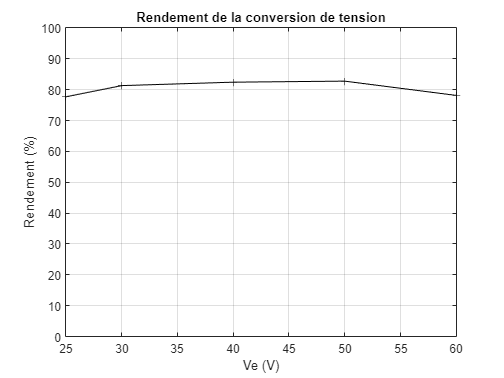


rendement=Ps./Pe*100;
plot(Ve2,rendement,'k+-');
title('Rendement de la conversion de tension')
xlabel('Ve (V)'); ylabel('Rendement (%)')
ylim([0 100])
grid on

%%%Vs=20V cst%%%